# **Robo: Bridge of Doom Challenge**

### **Authors: Berwin Lan and Cara Mulrooney**

## **Exercise 21.1**

1. For the Bridge of Doom, plot the parametric curve that defines the centerline of the bridge.

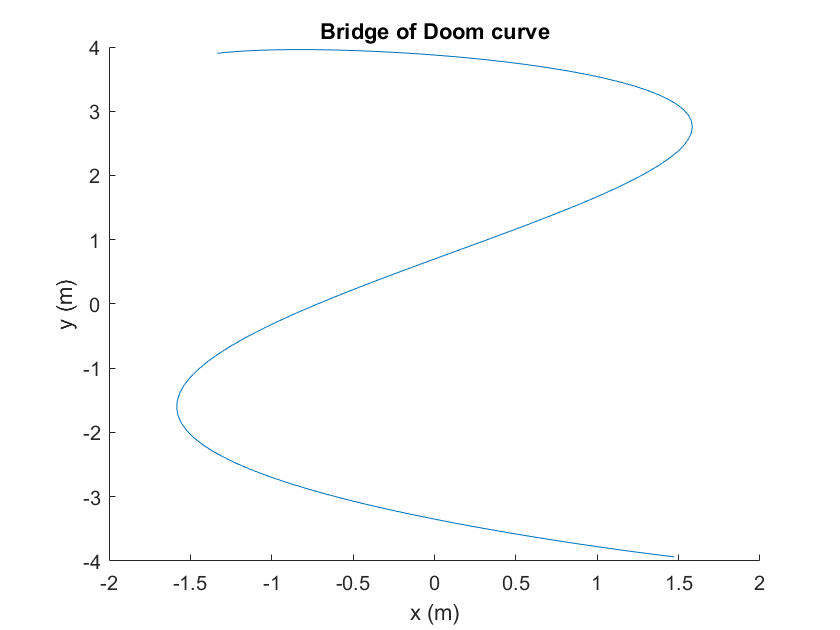

clc, clear all;

u = linspace(0, 3.2);   % seconds
ri = 4 * 0.396*cos(2.65*(u + 1.4)); % x-component of vector
rj = 4 * 0.99*sin(u + 1.4);         % y-component of vector

clf; hold on;
plot3(ri, rj, u);
title("Bridge of Doom curve"); xlabel("x (m)"); ylabel("y (m)");

2. On the same figure, plot the unit tangent and unit normal vectors at several points along the curve. You should have starter code to help with this in the Robo Homework 1 assignment.

syms u

ri = 4 * 0.396*cos(2.65*(u + 1.4)); % x-component of vector
rj = 4 * 0.99*sin(u + 1.4);         % y-component of vector
r = [ri, rj];

% find tangent vector
dr = diff(r, u);
assume(u,{'real','positive'});
T_hat=simplify(dr / norm(dr))

$$T\_hat = \begin{array}{l} \left(\begin{array}{cc} -\frac{53\,\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}{\sigma_{1}} & \frac{50\,\cos\left(u+\frac{7}{5}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(u+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$


% find normal vector
dT_hat=diff(T_hat,u);
N_hat=simplify(dT_hat / norm(dT_hat))

$$N\_hat = \begin{array}{l} \left(\begin{array}{cc} -\frac{2\,\left(483625\,\sigma_{6}+702250\,\sigma_{5}+218625\,\sigma_{4}\right)}{\sigma_{1}} & -\frac{561800\,\sin\left(u+\frac{7}{5}\right)+1025285\,\sigma_{3}+463485\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=265\,\sqrt{2809\,{\left(40\,\sin\left(u+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}+2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{10}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{10}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{20}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{20}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{20}+\frac{91}{100}\right) \end{array}$$

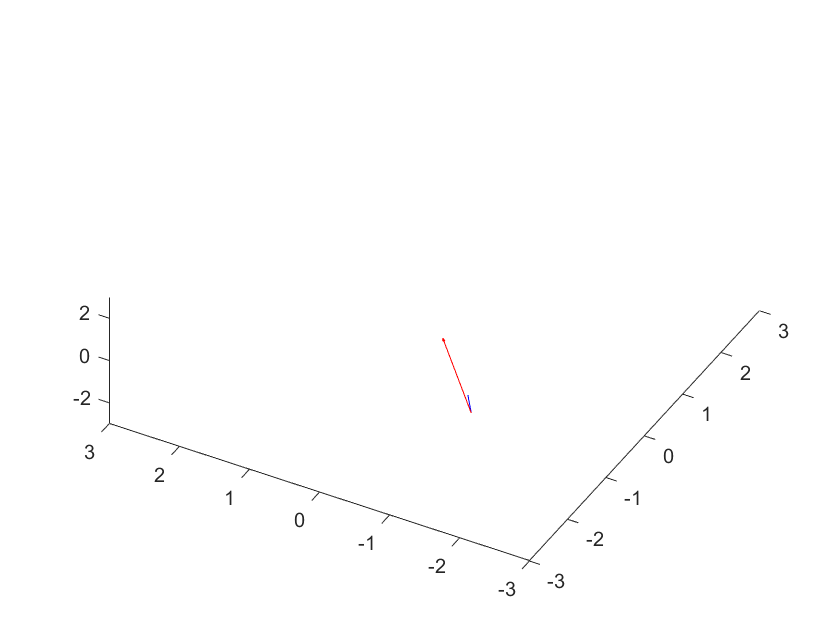

% If we wish to visualize this curve, we can make substitutions into our functions. 
u_num = linspace(0, 3.2, 100); % define a set of evenly spaced points between 0 and 2*pi

% we will also convert to a number of type double
for n=1:length(u_num)
    r_num(n,:) = double(subs(r, u, u_num));
    T_hat_num(n,:) = double(subs(T_hat, u, u_num));
    N_hat_num(n,:) = double(subs(N_hat, u, u_num));
    
    % we can also plot this using the quiver3 function
    plot3(r_num(:,1), r_num(:,2), r_num(:,3)), axis([-3 3 -3 3 -3 3]), hold on % plot the entire curve
    quiver3(r_num(n,1), r_num(n,2), r_num(n,3), T_hat_num(n,1), T_hat_num(n,2), T_hat_num(n,3), 'r') % plot the unit tangent
    quiver3(r_num(n,1), r_num(n,2), r_num(n,3), N_hat_num(n,1), N_hat_num(n,2), N_hat_num(n,3), 'b') % plot the unit normal
    hold off
    drawnow % force the graphic to update as it goes
end

Brent advice for verification: when you plot pos based on v it graphs correctly (overlay neato pos points on actual path of BoD)

## **Exercise 21.2**

## **Exercise 21.3**

## **Exercise 21.4**

## **Exercise 21.5**

## **Exercise 21.6**

Robo HW 1 Code:

%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms u

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4*(0.3960*cos(2.65*(u+1.4)));
rj=4*(-0.99*sin(u+1.4));
rk=0*u;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,t);

%velocity and speed
v=dr
speed=simplify(norm(v))


% we want to add some assumptions so that the algebra simplifies the way it
% should
assume(u,'positive') % u should be positive

%now we can use the simplify function to make things look nice
T_hat=simplify(v/norm(v))

%Next, we want to find the unit normal vector
dT_hat=diff(T_hat,t);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

%The unit binormal vector is found from the cross product of the unit
%tangent and unit normal
B_hat=cross(T_hat,N_hat);
B_hat=simplify(B_hat)

%We can also find the curvature
kappa=norm(dT_hat)/norm(dr);
kappa=simplify(kappa)

%How about the Torsion?
tau=-dot(N_hat,(diff(B_hat,t)/norm(dr)))
L = int((norm(dr)),0,2*pi)

%accelerations
accel=diff(v,t)

aN=simplify(dot(accel,N_hat))
aT=simplify(dot(accel,T_hat))

%angular velocity
w = cross(T_hat,dT_hat);
angular_velocity = simplify(w)

%left and right wheel velocities
d = 0.235; % wheel base
V_L = speed - angular_velocity*(d/2);
V_left_wheel = simplify(V_L)

V_R = speed + angular_velocity*(d/2);
V_right_wheel = simplify(V_R)
